# EE110B Lab 5

# Name: Buddy Ugwumba SID: 862063029

#### 1) Assume that the system between the voice $x\left\lbrack n\right\rbrack$ from your mouth and the acoutsic signal $y\left\lbrack n\right\rbrack$ picked up by a microphone is linear and time-invariant, and hence


$$y\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack =\sum_{l\;=1}^L h\left\lbrack l\right\rbrack x\left\lbrack n-1\right\rbrack$$


#### To see the effect of the echo distortion, assume


$$x\left\lbrack n\right\rbrack =\mathrm{sin}\left(\frac{\pi }{5}n\right)\left(u\left\lbrack n\right\rbrack -u\left\lbrack n-10\right\rbrack \right)$$


#### and also chose the echo coefficents $h\left\lbrack l\right\rbrack$ for all $0\le l\le 10$ randomly. Here L = 10. Plot $x\left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack$ for $0\le n\le 20$. Discuss the impact of $h\left\lbrack n\right\rbrack$ on $y\left\lbrack n\right\rbrack$ in relation to $x\left\lbrack n\right\rbrack$.

%n goes from 0 -9 due to the unit step function.
n = 0:1:9;
x_n = sin(pi/5*n);
% Plot the convolution
L = 10;
l = 0:1:L+1;
%Control random number generator so that we get the same random number
%everytime. 
rng(0)
h_l = randn(1,L+1);
y_n = conv(x_n, h_l);
fig = figure;
fig.Position = [100,100,1000,300];

Plot of $x\left\lbrack n\right\rbrack$

subplot(1,3,1);
stem(n,x_n, 'b', 'LineWidth',2);
xlabel('n');
ylabel('x[n]');
title('Input');
grid on;
grid minor;

subplot(1,3,2);
stem(h_l,'r','LineWidth',2);
xlabel('n');
ylabel('h[l]');
title('Impulse Response');
grid on
grid minor


Plot of $y\left\lbrack n\right\rbrack$

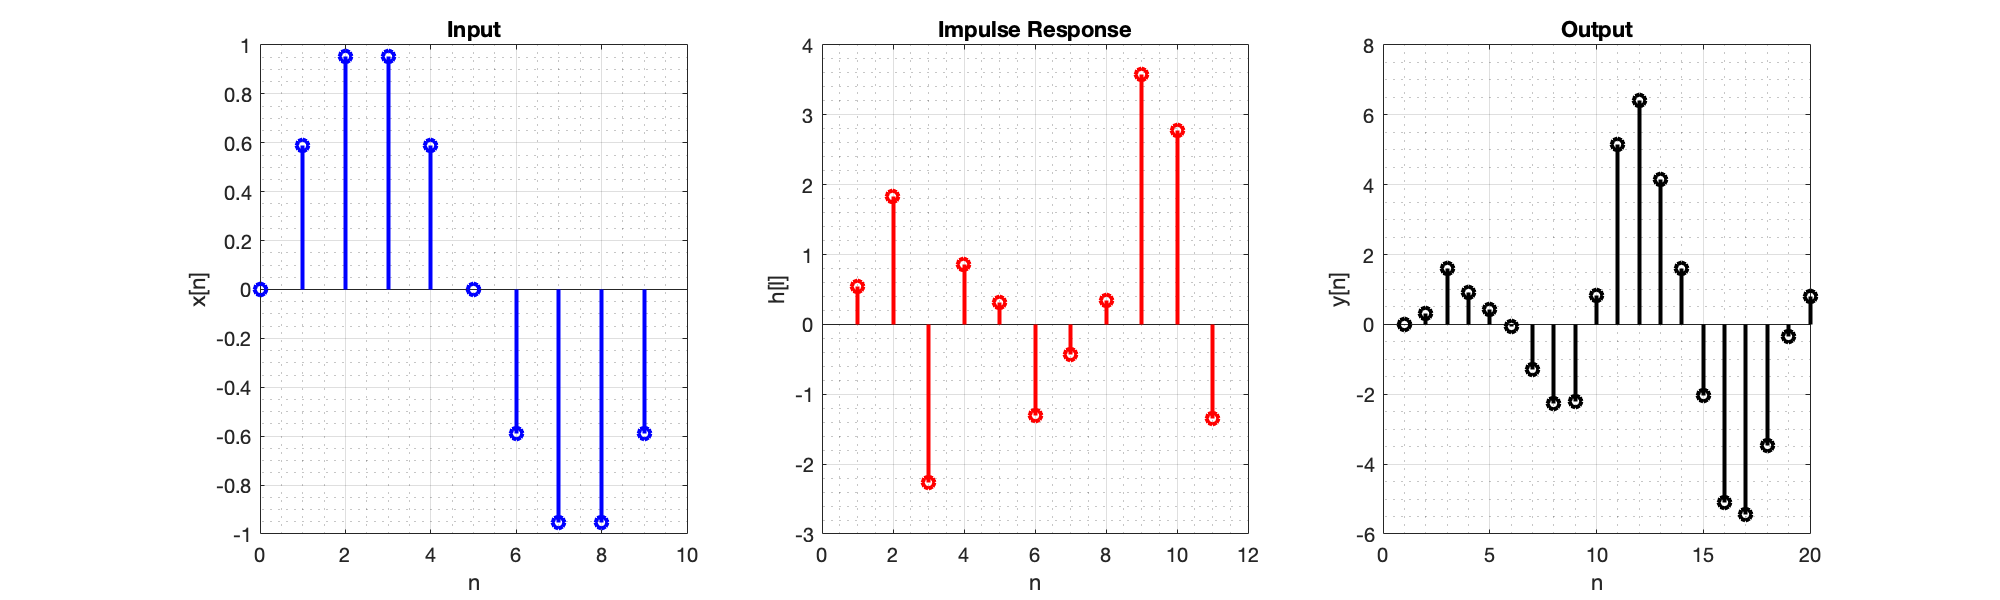

subplot(1,3,3);
stem(y_n, 'k', 'LineWidth',2);
xlabel('n');
ylabel('y[n]');
title('Output');
grid on;
grid minor;

Discuss the impact of $h\left\lbrack n\right\rbrack$ on $y\left\lbrack n\right\rbrack$ in relation to $x\left\lbrack n\right\rbrack$.

In relation to $x\left\lbrack n\right\rbrack$ the output $y\left\lbrack n\right\rbrack$is heavily distorted. I know this because the output is not an exact replica of the input signal $x\left\lbrack n\right\rbrack$. This distortion is due to varying amplitudial lengths of the impulse response. We know that in the frequency domain, every discrete time signal is periodic with a periodicity of 1. however, here we see that the signal repreats itself twice. The second half is the echo.  I surmise that the differences in amplitudes represent the varying anounts of intensities of the echos.

#### 2) Assume that the same $x\left\lbrack n\right\rbrack$ in (2) but $h\left\lbrack n\right\rbrack =0\ldotp {98}^n u\left\lbrack n\right\rbrack$ which is the impulse response of a first-order feedback system. 

####     a) Compute and plot $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$ for $0\le n\le 20$ (with a large L such that $h\left\lbrack L\right\rbrack$ is negligible). Discuss the distortion effect by $h\left\lbrack n\right\rbrack$

%h
L = 1000;
l = 0:1:L;
h_l = 0.98.^l;

Plot of $y\left\lbrack n\right\rbrack$

y_n = conv(x_n, h_l);
fig = figure;
fig.Position = [100, 100, 1200, 300];
subplot(1,4,1);
stem(n, x_n, 'b','LineWidth',2);
xlabel('n');
ylabel('x[n]');
title('Input');

subplot(1,4,2)
stem(l, h_l, 'r','LineWidth',2);
xlabel('n');
ylabel('h[l]');
title('Impulse Response');

subplot(1,4,3)
stem(y_n(1:20),'k','LineWidth',2);
xlabel('n');
ylabel('y[n]');
title('Output');

####     b) Compute and plot $v\left\lbrack n\right\rbrack =g\left\lbrack n\right\rbrack *y\left\lbrack n\right\rbrack$for $0\le n\le 20$ where $y\left\lbrack n\right\rbrack =\delta \left\lbrack n-5\right\rbrack -0\ldotp 98\delta \left\lbrack n-6\right\rbrack$. Discuss the quality of $g\left\lbrack n\right\rbrack$ as an echo cancellation filter

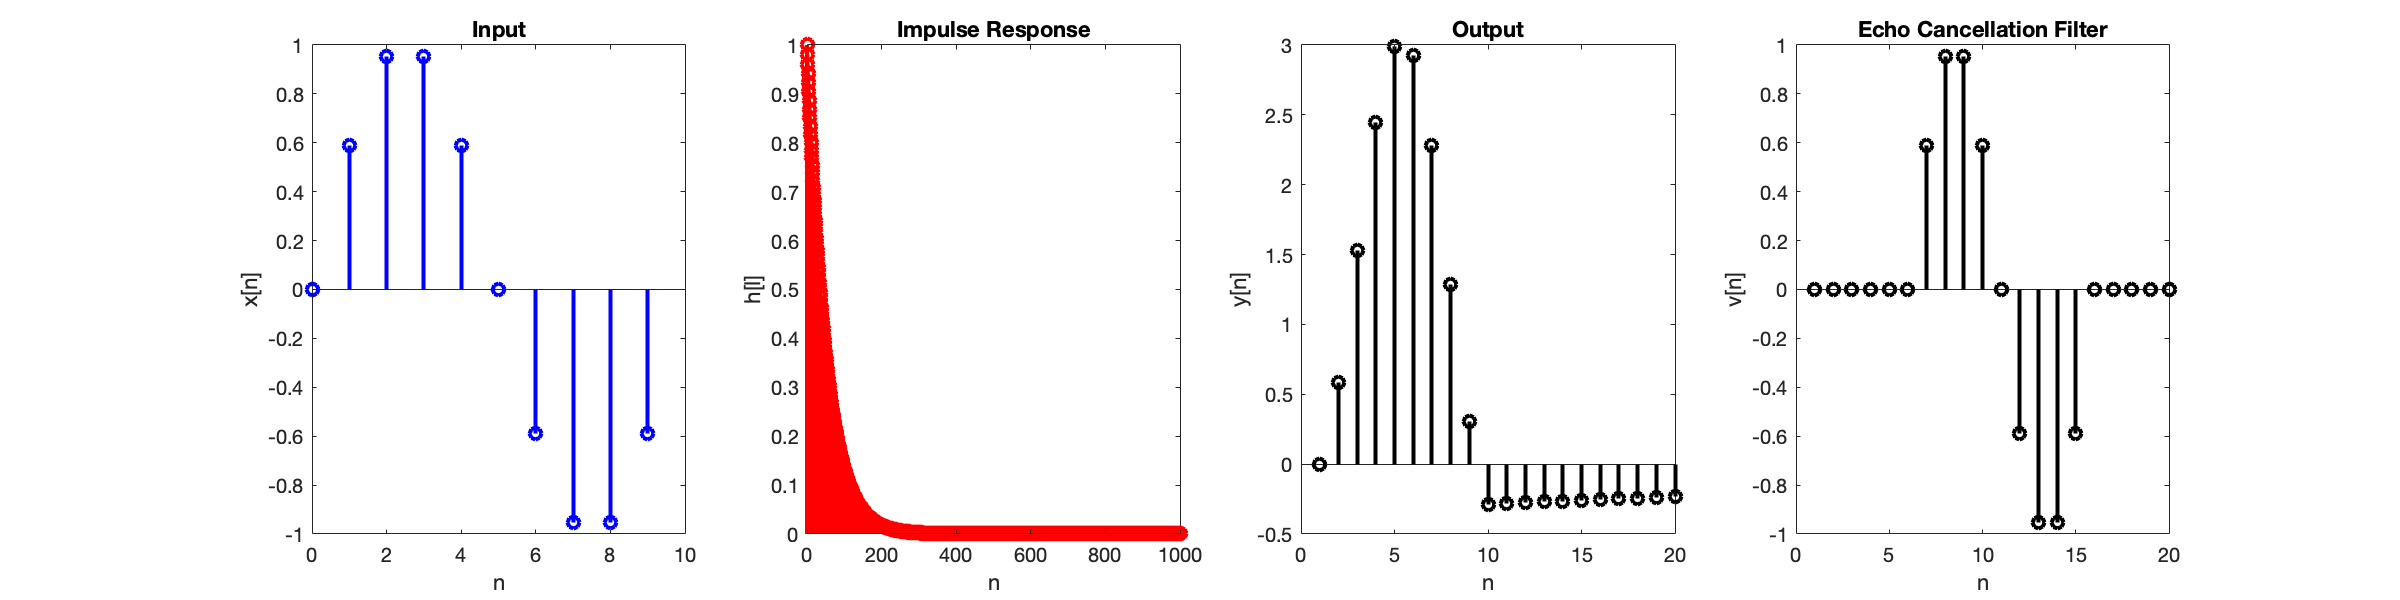

% echo cancellation
g_n = zeros(1, 100);
%Remember that arrays are indexed at 1, thus the value for the delta function equation is +1
g_n(6) = 1;
g_n(7) = -0.98;
v_n = conv(g_n,y_n);
subplot(1,4,4)
stem(v_n(1:20),'k','LineWidth',2);
xlabel('n');
ylabel('v[n]');
title('First Order Feedback Echo Cancellation Filter');

Discuss the distortion effects of $h\left\lbrack n\right\rbrack$

We can see the output is distorted still. We know this to be true because the output does not match the input. This distortion is due to varying ampltudial lengths of the impulse response. If the impulse had been a delta function, the output would have been a perfect copy of the signal just shifted based on the location of the delta function. Since h[n] is not a delta function but a train of delta functions with different amplitudes we have distortion. 

Discuss the quality of $g\left\lbrack n\right\rbrack$ as an echo cancellation filter

the g[n] looks exactly like the original signal with a delay of 6 units. Therefore, as an echo cancelation filter, I do not think that this works very well. The receiver will hear an echo due to the delayed time that is taken to transmit the message. If we want $g\left\lbrack n\right\rbrack$ to act more efficiently as a cancellation filter, we need less delay so that it is on par with the speakers message. 

#### 3) If $h\left\lbrack n\right\rbrack =a^n u\left\lbrack n\right\rbrack -b^n u\left\lbrack n\right\rbrack$ (which is the impulse response of a second-order feeback system), then its DTFT is $H\left(f\right)=\frac{1}{1-{\mathrm{ae}}^{-\mathrm{j2}\pi f} }-\frac{1}{1-{\mathrm{be}}^{-\mathrm{j2}\pi f} }=\frac{\left(a-b\right)e^{-\mathrm{j2}\pi f} }{1-\left(a+b\right)e^{-\mathrm{j2}\pi f} +{\mathrm{abe}}^{\mathrm{j4}\pi f} }$. A good inverse filter of $H\left(f\right)$ has the frequency response $G\left(f\right)=1-\left(a+b\right)e^{-\mathrm{j2}\pi f} +{\mathrm{abe}}^{-\mathrm{j4}\pi f}$. Assume the same $x\left\lbrack n\right\rbrack$in (2) but $h\left\lbrack n\right\rbrack =0\ldotp {98}^n u\left\lbrack n\right\rbrack -{\left(-0\ldotp 95\right)}^n u\left\lbrack n\right\rbrack$.

####     a) Compute and plot $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$ for $0\le n\le 20$ (with a large L such that $h\left\lbrack L\right\rbrack$ is negligible). Discuss the distortion effect by $h\left\lbrack n\right\rbrack$

%h
L = 1000;
l = 0:1:L;
h_l = 0.98.^l-(-0.95).^l;

Plot of $y\left\lbrack n\right\rbrack$

y_n = conv(x_n, h_l);
fig = figure;
fig.Position = [100, 100, 1200, 300];
subplot(1,4,1);
stem(n, x_n, 'b','LineWidth',2);
xlabel('n');
ylabel('x[n]');
title('Input');

subplot(1,4,2)
stem(l, h_l, 'r','LineWidth',2);
xlabel('n');
ylabel('h[l]');
title('Impulse Response');

subplot(1,4,3)
stem(y_n(1:20),'k','LineWidth',2);
xlabel('n');
ylabel('y[n]');
title('Output');

####     b) Compute and plot $v\left\lbrack n\right\rbrack =g\left\lbrack n\right\rbrack *y\left\lbrack n\right\rbrack$for $0\le n\le 20$ where $y\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack -\left(a+b\right)\delta \left\lbrack n-1\right\rbrack +\mathrm{ab}\delta \left\lbrack n-2\right\rbrack ,a=0\ldotp 98$ and $b=-0\ldotp 95$. Discuss the quality of $g\left\lbrack n\right\rbrack$ as an echo cancellation filter

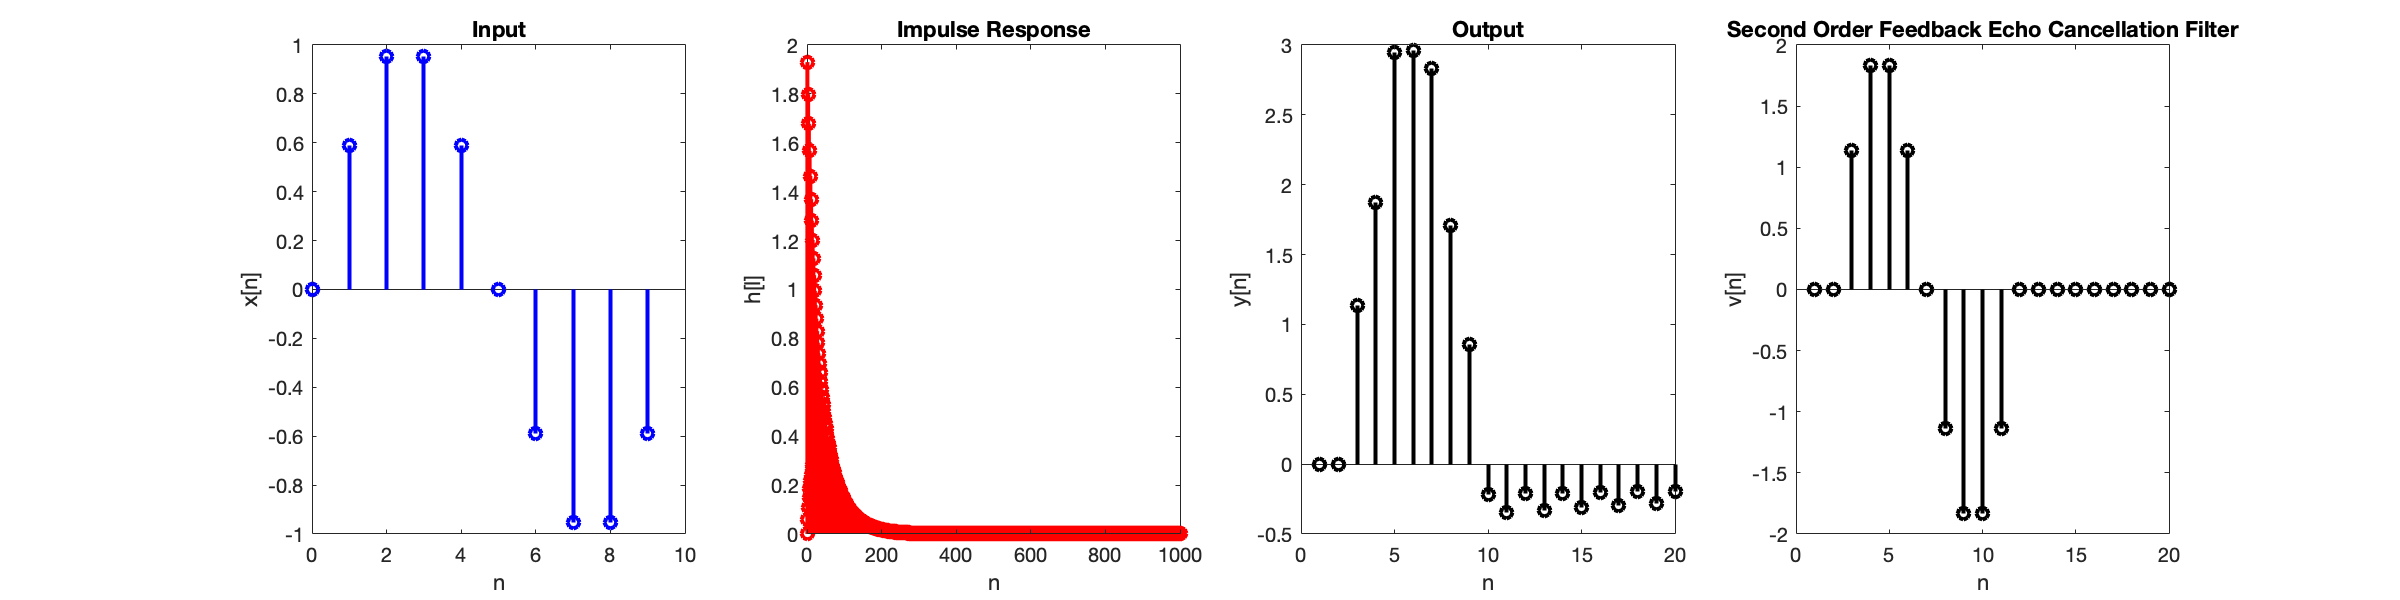

% echo cancellation
g_n = zeros(1, 100);
%Remember that arrays are indexed at 1, thus the value for the delta function equation is +1
a = 0.98;
b = (-0.95);
g_n(1) = 1;
g_n(2) = -(a+b);
g_n(3) = (a*b);
v_n = conv(g_n,y_n);
subplot(1,4,4)
stem(v_n(1:20),'k','LineWidth',2);
xlabel('n');
ylabel('v[n]');
title('Second Order Feedback Echo Cancellation Filter');

Discuss the distortion effects of $h\left\lbrack n\right\rbrack$

We can see the output is distorted still. We know this to be true because the output does not match the input. This distortion is due to varying ampltudial lengths of the impulse response. If the impulse had been a delta function, the output would have been a perfect copy of the signal just shifted based on the location of the delta function. Since h[n] is not a delta function but a train of delta functions with different amplitudes we have distortion. However, the distortion is less than in 2 because the amplitude of the impulse response for this one sided exponential function is greater than 1. 

Discuss the quality of $g\left\lbrack n\right\rbrack$ as an echo cancellation filter

the g[n] looks exactly like the original signal with a delay of  around 3 units. Therefore, as an echo cancelation filter, I do think that this works much better than the first-order feedback system. The receiver might hear a slight echo due to the delayed time that is taken to transmit the message. If we want $g\left\lbrack n\right\rbrack$ to act more efficiently as a cancellation filter, we need less delay so that it is on par with the speakers message. This can be done by changing the parameters of a and b. 